**Implementation of :**

### ***A Single Backlit Image Enhancement Method For Improvement Of Visibility Of Dark Part***

**Published in: 2021 IEEE International Conference on Image Processing (ICIP)**

**Authors: **

[Masato Akai](https://ieeexplore.ieee.org/author/37089384056)

Yamaguchi University

[Yoshiaki Ueda](https://ieeexplore.ieee.org/author/37075106000)

Fukuoka University

[Takanori Koga](https://ieeexplore.ieee.org/author/37889504000)

Kindai University

[Noriaki Suetake](https://ieeexplore.ieee.org/author/37285071000)

Yamaguchi University

**TERM PROJECT**

**Name : Ifrah Asif Hasan (Indian Institute of Technology, Kharagpur)**

**Roll Number : 19EE38028**

Original Image taken as rgb with size of :**720x960.**

I_rgb = imread('SunsetGirl.jpg');

Converting rgb to gray using `0.2989 * R + 0.5870 * G + 0.1140 * B`**.**

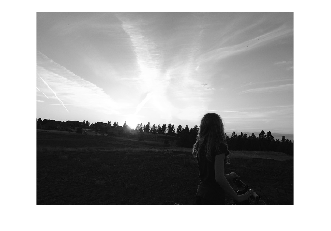

I = rgb2gray(I_rgb);
imshow(I)

imhist(I)

imshow(I_rgb)

Using *Gamma Correction* with **Gamma = 0.5**.

I_Gamma = imadjust(I,[],[],0.5);
imhist(I_Gamma)

imshow(I_Gamma)

Using *Histogram Equilization*.

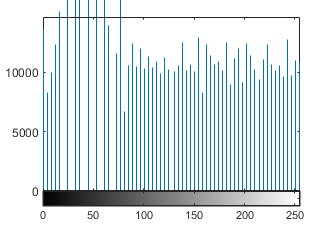

I_HisEq = histeq(I);
imhist(I_HisEq)

imshow(I_HisEq)

Blending them by *Alpha-Blending Method*; **Alpha is 0.2** .

Ibg = I_HisEq;
Ifg = I_Gamma;

if length(size(Ibg))==3
        Ibg=rgb2gray(Ibg);
end
if length(size(Ifg))==3
        Ifg=rgb2gray(Ifg);
end

alpha = 0.2;

[row,col] = size(Ibg);
O = zeros(row,col);
O = uint8(I);
for i = 1:row
    for j = 1:col
        O(i,j) = alpha * Ibg(i,j) + (1 - alpha) * Ifg(i,j);
    end
end



imshow(Ibg);

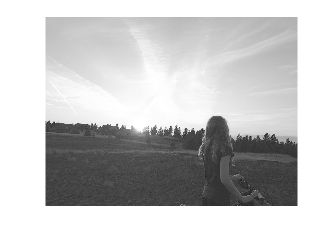

imshow(Ifg);

imshow(O);

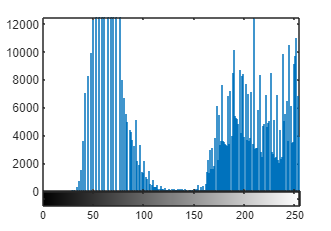

imhist(O);

Histogram : Threshold is calculated using *Otsu's Method* and shown with a bright red line.

**Threshold is 0.4157.**

imhist(I)
t = otsuthresh(histcounts(I,-0.5:255.5))

t = 0.4157

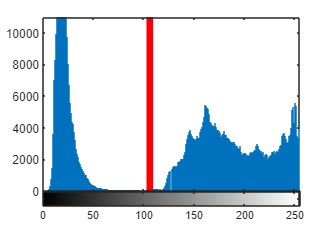

hold on
plot(255*[t t], ylim, 'r', 'LineWidth', 5)
hold off

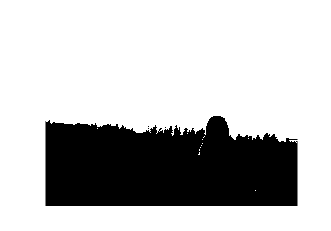

W = imbinarize(I,t);

% [row,col] = size(I);
% W = zeros(row,col);
% I_t = I./255;
% for i = 1:row
%     for j = 1:col
%         if(I_t(i,j) < t)
%             W(i,j) =  1;
%         else
%             W(i,j) = 0;
%         end
%     end
% end

imshow(W)

Using *Guided Filter* on A with I as the guide,Taking **NeighborhoodSize as 41(2r +1) r = 20 .**

Without specifying the size, a better result is observed.

W = imcomplement(W);

W = imguidedfilter(W,I);

X = imcomplement(W);

Converting into proper format.

W = uint8(W);
X = uint8(X);

Constructing the Final RGB Image

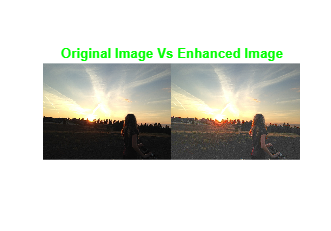

O_Temp = W.*O + X.*I;

O_rgb = I_rgb.*(O_Temp./I);
imshowpair(I_rgb,O_rgb,'montage')
title("Original Image Vs Enhanced Image",'Color','g','FontSize',10)

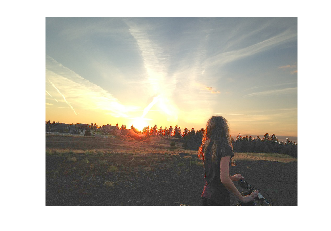

imshow(O_rgb)

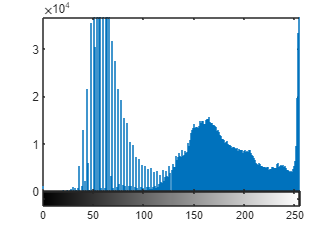

imhist(O_rgb)

Calculation of **Naturalness Image Quality Evaluator (NIQE)**.

We get a nearly equal result as compared to the Research Paper : **Paper --> 2.31 Our Result --> 2.2789**

niqe(O_rgb)

ans = 2.4716

Calculation of **Lightness Order Error (LOE) **.

We get a nearly equal result as compared to the Research Paper : **Paper --> 134 Our Result --> 142.0537**


LOE(I_rgb,O_rgb)

LOE = 76.0761

 function LOE(A,B)
        %input image
        %ipic=imread('Input.bmp');
        ipic=A;
        ipic=double(ipic);
        %enhanced image
        %epic=imread('Enhanced.JPG');
        epic=B;
        epic=double(epic);
        
        [m,n,k]=size(ipic);

        
        %get the local maximum for each pixel of the input image
        win=7;
        imax=round(max(max(ipic(:,:,1),ipic(:,:,2)),ipic(:,:,3)));
        imax=getlocalmax(imax,win);
        %get the local maximum for each pixel of the enhanced image
        emax=round(max(max(epic(:,:,1),epic(:,:,2)),epic(:,:,3)));
        emax=getlocalmax(emax,win);
        
        %get the downsampled image
        blkwin=50;
        mind=min(m,n);
        step=floor(mind/blkwin);% the step to down sample the image
        blkm=floor(m/step);
        blkn=floor(n/step);
        ipic_ds=zeros(blkm,blkn);% downsampled of the input image
        epic_ds=zeros(blkm,blkn);% downsampled of the enhanced image
        LOE=zeros(blkm,blkn);%
        
        for i=1:blkm
            for j=1:blkn
                ipic_ds(i,j)=imax(i*step,j*step);
                epic_ds(i,j)=emax(i*step,j*step);
            end
        end

        for i=1:blkm
            for j=1:blkn%bug
                flag1=ipic_ds>=ipic_ds(i,j);
                flag2=epic_ds>=epic_ds(i,j);
                flag=(flag1~=flag2);
                LOE(i,j)=sum(flag(:));
            end
        end
        
        LOE=mean(LOE(:))
    end
    
    function output=getlocalmax(pic,win)
        [m,n]=size(pic);
        extpic=getextpic(pic,win);
        output=zeros(m,n);
        for i=1+win:m+win
            for j=1+win:n+win
                modual=extpic(i-win:i+win,j-win:j+win);
                output(i-win,j-win)=max(modual(:));
            end
        end
    end
    
    function output=getextpic(im,win_size)
        [h,w,c]=size(im);
        extpic=zeros(h+2*win_size,w+2*win_size,c);
        extpic(win_size+1:win_size+h,win_size+1:win_size+w,:)=im;
        for i=1:win_size%extense row
            extpic(win_size+1-i,win_size+1:win_size+w,:)=extpic(win_size+1+i,win_size+1:win_size+w,:);%top edge
            extpic(h+win_size+i,win_size+1:win_size+w,:)=extpic(h+win_size-i,win_size+1:win_size+w,:);%botom edge
        end
        for i=1:win_size%extense column
            extpic(:,win_size+1-i,:)=extpic(:,win_size+1+i,:);%left edge
            extpic(:,win_size+w+i,:)=extpic(:,win_size+w-i,:);%right edge
        end
        output=extpic;
    end
    
